#                                                             Henrique Silveira Dutra

#                                                                      202110538

#                                      Laboratório de Sistemas de Comunicação Digital I

#                                                                 Experimento 5

Considerando um transmissor que utiliza modulação QPSK, e opera com:

-  SymbolRate = 16.6MHz 

- Frequência da portadora = 32MHz

- Fator de upsample: $k = 16$

### 1. Implemente uma função que realiza o processo de mapeamento (mapper QPSK). A função recebe como argumento o *bitstream* de entrada do modulador e retorna dois vetores com a parte real $I$ e a parte imaginária $Q$ do símbolo IQ complexo. Verifique o seu funcionamento da função através de um *bitstream* que contemple todas as possíveis combinações de 2 bits. 

% Bitstream de entrada com todas as combinações de 2 bits
input_bits0 = [1 0 1 0 1 0 1 0];
input_bits1 = [1 0 0 1 1 0 1 0];

% Gerar 10000 bits aleatórios
num_bits = 1e4;
bitstream = randi([0, 1], 1, num_bits);

% Chamando a função QPSK_mapper
[I0, Q0] = mapper_QPSK(input_bits0);

% Exibindo os resultados
disp('Parte Real:');

Parte Real:


disp(I0);

     1     1     1     1



disp('Parte Imaginária:');

Parte Imaginária:


disp(Q0);

    -1    -1    -1    -1



### 2. Considere que, em um determinado instante de tempo, o bitstream na entrada do mapper é dado por $B_0 = {... 10101010 ...}$. Plote a sequência de símbolos IQ na saída do mapper e a constelação. Analise os resultados. 

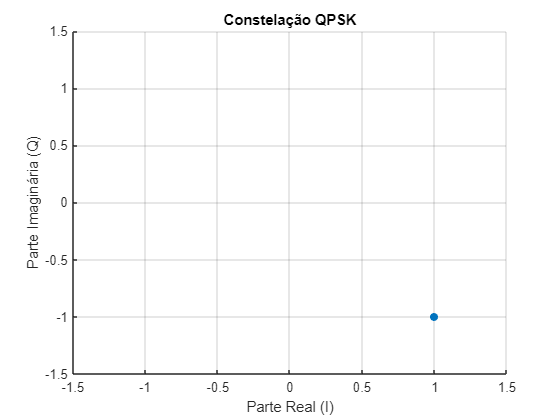

% Plot constelação dos símbolos IQ
figure;
scatter(I0, Q0, 'filled');
xlabel('Parte Real (I)');
ylabel('Parte Imaginária (Q)');
title('Constelação QPSK');
grid on;
axis([-1.5 1.5 -1.5 1.5]);

Como pode ser visto na figura acima, a função implementada atribui ao símbolo IQ(10) a posição correta na constelação, respeitando a distribuição dos símbolos na modulação QPSK. I(parte real) = 1 e Q(parte imaginária) = -1.

### 3. Implemente o *upsampling* de $I$ e $Q$ (inserindo $k-1$ amostras com valor zero após cada amostra de $I$ e $Q$). Plote os gráficos de $I$ e $Q$ após o *upsampling*. Verifique os resultados.

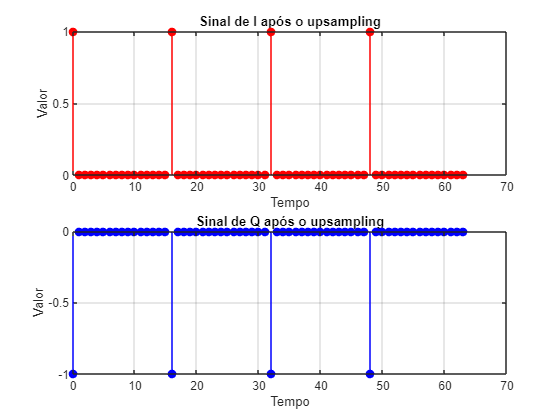

% Fator de upsample
k = 16;

% Upsampling de I e Q
I0_upsampled = upsample(I0, k);
Q0_upsampled = upsample(Q0, k);

% Vetor de tempo após o upsampling
t0_upsampled = (0:length(I0_upsampled)-1);

% Plot dos gráficos de I e Q após o upsampling
figure;
subplot(2, 1, 1);
stem(t0_upsampled, I0_upsampled, 'r', 'filled');
xlabel('Tempo');
ylabel('Valor');
title('Sinal de I após o upsampling');
grid on;

subplot(2, 1, 2);
stem(t0_upsampled, Q0_upsampled, 'b', 'filled');
xlabel('Tempo');
ylabel('Valor');
title('Sinal de Q após o upsampling');
grid on;

O sinal modulado (IQ) originalmente está na taxa de símbolos, ou seja, com 1 amostra por símbolo. Isso não é suficiente para representar bem a forma do sinal após passar por um filtro de forma de pulso. O upsample adiciona zeros entre os símbolos, e o filtro posterior (LPF ou shaping filter) interpola esses pontos. Além disso, filtros digitais requerem um número mínimo de amostras por ciclo para operar corretamente. Se mantiver uma taxa baixa, o filtro pode deformar o espectro. O DDS, usa uma portadora para transladar o sinal para banda passante. Para isso funcionar corretamente, o sinal IQ precisa estar com uma taxa de amostragem suficientemente alta para evitar aliasing durante a translação espectral e gerar uma forma de onda analógica precisa após o D/A.

### 4. Considere a resposta ao impulso $h(n)$ do filtro retangular apresentada na figura abaixo. Plote e analise a resposta em frequência do filtro.

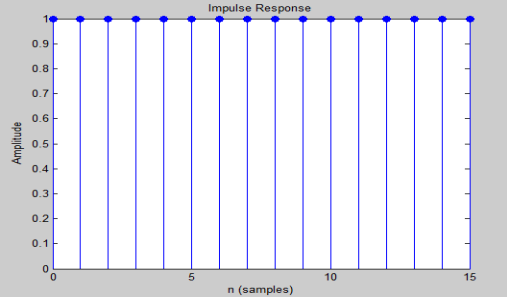

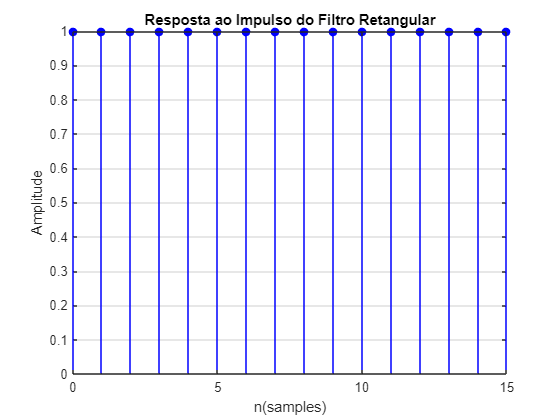

% Resposta ao impulso de um filtro retangular de 16 amostras
h = ones(1, k);
m = 0:length(h)-1;

% Plot da resposta ao impulso
figure;
stem(m,h, 'filled', 'b');
xlabel('n(samples)');
ylabel('Amplitude');
title('Resposta ao Impulso do Filtro Retangular');
grid on;

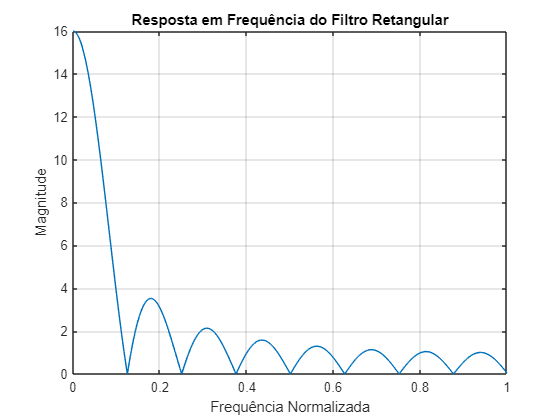


% Cálculo da resposta em frequência do filtro
H = freqz(h);

% Frequências normalizadas
frequencies = linspace(0, 1, length(H));

% Plot da resposta em frequência
figure;
plot(frequencies, abs(H));
xlabel('Frequência Normalizada');
ylabel('Magnitude');
title('Resposta em Frequência do Filtro Retangular');
grid on;

Como é de conhecimento de sinais e sistemas, a resposta em frequência do filtro retangular é uma sinc(x), este sinal apresenta lóbulos laterais com amplitudes decrescentes. O uso deste filtro será discutido nos próximos itens.

### 5. Aplique a sequência 𝐼 e a sequência 𝑄, obtidas nas saídas dos upsamplers, ao LPF. Plote os gráficos de 𝐼 e 𝑄 após o LPF. Verifique e analise os resultados.

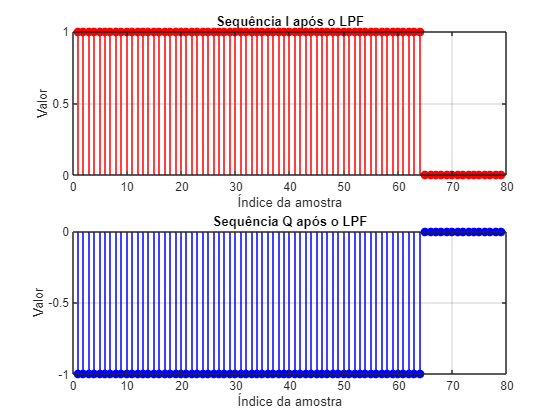

lpf_1 = h;

% Aplicação do LPF às sequências I e Q
I0_filtrado = conv(I0_upsampled,lpf_1);
Q0_filtrado = conv(Q0_upsampled,lpf_1);

% Plot dos gráficos de I e Q após o LPF 
figure; 
subplot(2,1,1);
stem(I0_filtrado, 'r', 'filled');
xlabel('Índice da amostra');
ylabel('Valor');
title('Sequência I após o LPF');
grid on;

subplot(2,1,2);
stem(Q0_filtrado, 'b', 'filled');
xlabel('Índice da amostra');
ylabel('Valor');
title('Sequência Q após o LPF');
grid on;

Como pode ser visto na figura acima, a sequencia IQ após upsample é convoluída com o filtro retangular e obtemos as sequências IQ após o LPF. Como I = 1 e Q = -1 para a sequência de bits utilizada, o comportamento esperado está correto. O próximo passo é realizar a heterodinação.

### 6. Implemente o processo de heterodinação e encontre a sequência $u\left(n\right)$ aplicada a entrada do D/A. Plote $u\left(n\right)$ e identifique o início e fim de cada símbolo IQ. Analise os resultados.

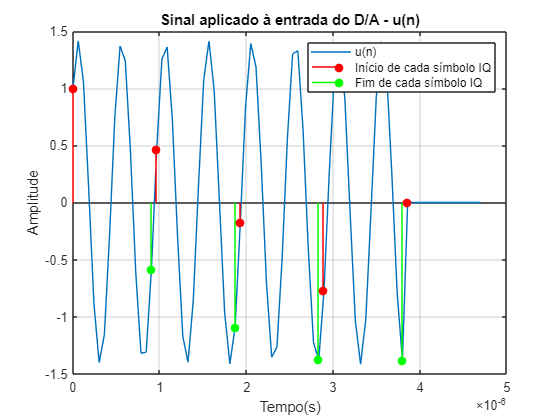

SR = 16.6e6; % Symbol Rate
Fc = 32e6; % Frequência da portadora
Fs = SR*k; % Frequência de amostragem
T = 1/SR; 

N0 = length(I0_filtrado);
n0 = 0:N0-1;

% Sinal da portadora
carrier_I0 = cos(2*pi*(Fc/Fs)*n0);
carrier_Q0 = sin(2*pi*(Fc/Fs)*n0);

% Heterodinação
u0 = I0_filtrado .* carrier_I0 - Q0_filtrado .* carrier_Q0;

t0 = 0:T:(length(I0_filtrado)-1)*T;

% Plot de u(n)
figure; 
plot(t0,u0);
xlabel('Tempo(s)');
ylabel('Amplitude');
title('Sinal aplicado à entrada do D/A - u(n)');
grid on;

% Identificação do início e fim de cada símbolo IQ
hold on;
stem(t0(1:k:end), u0(1:k:end), 'r', 'filled');
stem(t0(16:k:end), u0(16:k:end), 'g', 'filled');
legend('u(n)', 'Início de cada símbolo IQ', 'Fim de cada símbolo IQ');

O DDS usa uma portadora para realizar a heterodinação, que translada o sinal de banda base para banda passante. Como pode ser visto acima, o sinal aplicado à entrada do D/A é um sinal oscilatório sem inversão de fase, já que estamos usando uma sequência de bits que o mapper mapeia o mesmo símbolo.

### 7. Transforme $u\left(n\right)$ para o domínio da frequência $U\left(e^{j\omega } \right)$. Plote o módulo de  $U\left(e^{j\omega } \right)$ para $0\le \omega <\pi$, em função da frequência em MHz. Lembre-se que $f=\frac{\omega \cdot F_s }{\pi \cdot \;2}$, e onde, 𝐹𝑠 = 𝑓𝑟𝑒𝑞𝑢ê𝑛𝑐𝑖𝑎 𝑑𝑒 𝑎𝑚𝑜𝑠𝑡𝑟𝑎𝑔𝑒𝑚 𝑑𝑜 𝐷𝐴. Analise, interprete e comente os resultados. Compare a largura de banda do sinal em banda base com a largura de banda do sinal em banda passante.

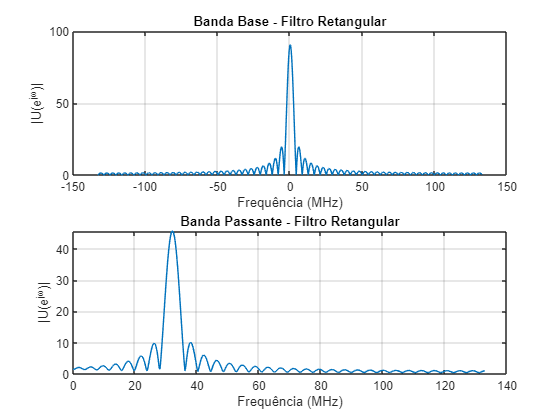

U0 = fft(u0, 1024);
U0 = U0(1:(length(U0))/2);

% Frequências normalizadas 
omega0 = linspace(0, pi, length(U0));

% Convertendo para frequências em MHz
f_MHz_U0 = omega0/pi * (Fs/2)/1e6;

% Obtendo o espectro em banda base
bb_ret = I0_filtrado + 1j*Q0_filtrado;
BB_ret = fftshift(fft(bb_ret,1024));
fBB_ret = linspace(-Fs/2,Fs/2, length(BB_ret))/1e6;

% Plot do módulo de U(e^(jw))
figure; 
subplot(2,1,1)
plot(fBB_ret, abs(BB_ret));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Banda Base - Filtro Retangular');
grid on;

subplot(2,1,2)
plot(f_MHz_U0, abs(U0));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Banda Passante - Filtro Retangular');
grid on;

A figura acima é uma comparação entre o sinal em banda base e banda passante. O sinal em banda base foi obtido após a convolução do filtro com a sequência IQ(após upsample) e antes da heterodinação, realizando (y = I(filtrado) + jQ(filtrado)). É notório que ao realizar a translação em frequência ($f=32$MHz) a largura de banda duplica, analisando o lóbulo principal, e a amplitude é reduzida pela metade. Este comportamento é esperado já que ao transladar o sinal é realizada a operação $\frac{1}{2}\left\lbrack G\left(f-f_0 \right)+G\left(f+f_0 \right)\right\rbrack \ldotp$ Importante salientar que a análise é feita apenas na componente espectral positiva.

Analisando, obtemos a sinc(x) proveniente da resposta em frequência do filtro retangular utilizado. O espectro do sinal abrange muitas frequências pelos lóbulos laterais decrescentes da sinc(x), o que não é adequado para situações em que é levado em consideração a largura de banda operacional. Para isso iremos fazer análises com outros shaping filters nos próximos itens. 

### 8. Considere agora o bitstream na entrada do mapper dado por $B_1 =\left\lbrace \ldotp \ldotp \ldotp 10011010\ldotp \ldotp \right\rbrace$. Repita os passos anteriores. Analise, interprete e comente os resultados. Compare os resultados obtidos com as sequências $B_0$ e $B_1$. 

% Chamando a função QPSK_mapper
[I01, Q01] = mapper_QPSK(input_bits1);

% Exibindo os resultados
disp('Parte Real:');

Parte Real:


disp(I01);

     1    -1     1     1



disp('Parte Imaginária:');

Parte Imaginária:


disp(Q01);

    -1     1    -1    -1



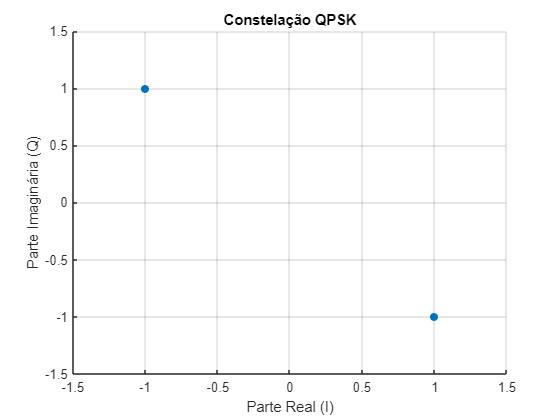


% Plot constelação dos símbolos IQ
figure;
scatter(I01, Q01, 'filled');
xlabel('Parte Real (I)');
ylabel('Parte Imaginária (Q)');
title('Constelação QPSK');
grid on;
axis([-1.5 1.5 -1.5 1.5]);

Diferentemente da primeira análise, o mapper QPSK mapeia a sequência de bits em dois símbolos distânciados em ${180}^{\circ }$. O comportamento dessa mudança é analisado nos próximos itens.

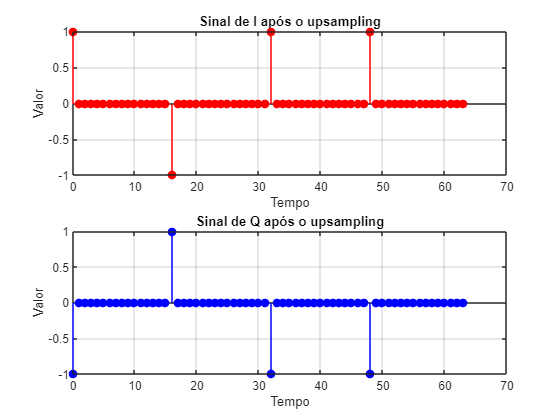

% Upsampling de I e Q
I01_upsampled = upsample(I01, k);
Q01_upsampled = upsample(Q01, k);

% Vetor de tempo após o upsampling
t01_upsampled = (0:length(I01_upsampled)-1);

% Plot dos gráficos de I e Q após o upsampling
figure;
subplot(2, 1, 1);
stem(t01_upsampled, I01_upsampled, 'r', 'filled');
xlabel('Tempo');
ylabel('Valor');
title('Sinal de I após o upsampling');
grid on;

subplot(2, 1, 2);
stem(t01_upsampled, Q01_upsampled, 'b', 'filled');
xlabel('Tempo');
ylabel('Valor');
title('Sinal de Q após o upsampling');
grid on;

Como pode ser visto na sequência após upsample, o símbolo 01 (I = -1 e Q  = 1) é diferente dos demais símbolos da sequência, assim o upsample não apresenta mais o símbolo I ou Q igual para todos os símbolos da sequência como visto na análise anterior.

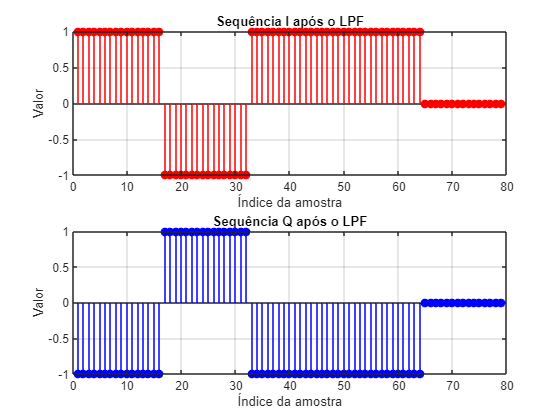

% Aplicação do LPF às sequências I e Q
I01_filtrado = conv(I01_upsampled,lpf_1);
Q01_filtrado = conv(Q01_upsampled,lpf_1);

% Plot dos gráficos de I e Q após o LPF 
figure; 
subplot(2,1,1);
stem(I01_filtrado, 'r', 'filled');
xlabel('Índice da amostra');
ylabel('Valor');
title('Sequência I após o LPF');
grid on;

subplot(2,1,2);
stem(Q01_filtrado, 'b', 'filled');
xlabel('Índice da amostra');
ylabel('Valor');
title('Sequência Q após o LPF');
grid on;

Como pode ser visto na figura acima, a sequencia IQ após upsample é convoluída com o filtro retangular e obtemos as sequências IQ após o LPF. Como o símbolo 01(I = -1 e Q = 1) e os demais símbolos 10(I = 1 e Q = -1), o comportamento esperado está correto. O próximo passo é realizar a heterodinação.

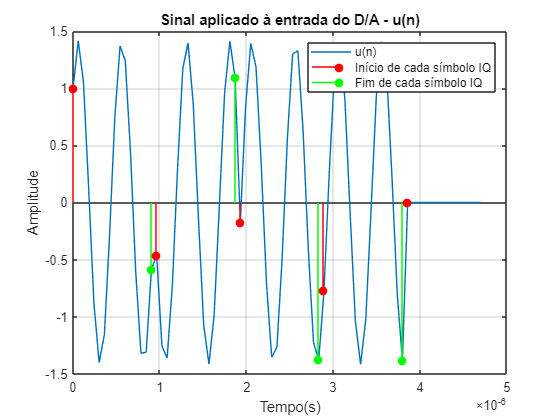

N01 = length(I01_filtrado);
n01 = 0:N01-1;

% Sinal da portadora
carrier_I01 = cos(2*pi*(Fc/Fs)*n01);
carrier_Q01 = sin(2*pi*(Fc/Fs)*n01);

% Heterodinação
u01 = I01_filtrado .* carrier_I01 - Q01_filtrado .* carrier_Q01;

t01 = 0:T:(length(I01_filtrado)-1)*T;

% Plot de u(n)
figure; 
plot(t01,u01);
xlabel('Tempo(s)');
ylabel('Amplitude');
title('Sinal aplicado à entrada do D/A - u(n)');
grid on;

% Identificação do início e fim de cada símbolo IQ
hold on;
stem(t01(1:k:end), u01(1:k:end), 'r', 'filled');
stem(t01(16:k:end), u01(16:k:end), 'g', 'filled');
legend('u(n)', 'Início de cada símbolo IQ', 'Fim de cada símbolo IQ');

O DDS usa uma portadora para realizar a heterodinação, que translada o sinal de banda base para banda passante. Como pode ser visto acima, o sinal aplicado à entrada do D/A é um sinal oscilatório com inversão de fase, já que temos dois símbolos distantes em ${180}^{\circ }$. Essa inversão de fase pode ser vista em $1\mu s$ e $2\mu s$.

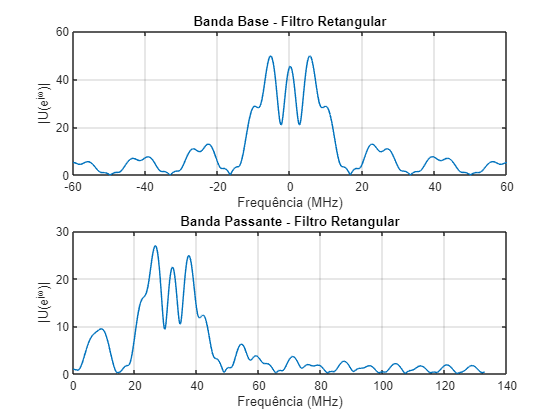

U01 = fft(u01,2048);
U01 = U01(1:(length(U01))/2);

% Frequências normalizadas 
omega01 = linspace(0, pi, length(U01));

% Convertendo para frequências em MHz
f_MHz_U01 = omega01/pi * (Fs/2)/1e6;

% Obtendo o espectro em banda base
bb_ret1 = I01_filtrado + 1j*Q01_filtrado;
BB_ret1 = fftshift(fft(bb_ret1,2048));
fBB_ret1 = linspace(-Fs/2,Fs/2, length(BB_ret1))/1e6;

% Plot do módulo de U(e^(jw))
figure; 
subplot(2,1,1);
plot(fBB_ret1, abs(BB_ret1));
xlabel('Frequência (MHz)');
xlim([-60 60]);
ylabel('|U(e^{j\omega})|');
title('Banda Base - Filtro Retangular');
grid on;

subplot(2,1,2);
plot(f_MHz_U01, abs(U01));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Banda Passante - Filtro Retangular');
grid on;

É notório que ao realizar a translação em frequência ($f=32$MHz) a largura de banda duplica, analisando o lóbulo principal, e a amplitude é reduzida pela metade. Este comportamento é esperado já que ao transladar o sinal é realizada a operação $\frac{1}{2}\left\lbrack G\left(f-f_0 \right)+G\left(f+f_0 \right)\right\rbrack \ldotp$ Importante salientar que a análise é feita apenas na componente espectral positiva.

Analisando, obtemos a sinc(x) proveniente da resposta em frequência do filtro retangular utilizado. O espectro do sinal abrange muitas frequências pelos lóbulos laterais decrescentes da sinc(x), o que não é adequado para situações em que é levado em consideração a largura de banda operacional. Em particular, as modulações M-PSK geram um amplo espectro de espúrios espectrais nos instantes em que ocorrem variações abruptas no sinal gerado no domínio tempo. Estes espúrios espectrais são particularmente intensos quando ocorre a transição entre símbolos angularmente distantes de 180° na constelação da modulação M-PSK. Na constelação QPSK mostrada anteriormente ocorrem transições entre símbolos antipodais para as sequências de 2 bits no bitstream de entrada do mapper dadas por 01 e 10 que resultam em transições abruptas de 180°.

Para obtermos um espectro que não contenha lóbulos laterais que abrange altas frequências, iremos fazer análises com outros shaping filters nos próximos itens.  

### 9. Substitua o LPF pelo filtro FIR gaussiano

### 10. Plote a resposta ao impulso e resposta em frequência do filtro gaussiano. Compare com a resposta do filtro retangular

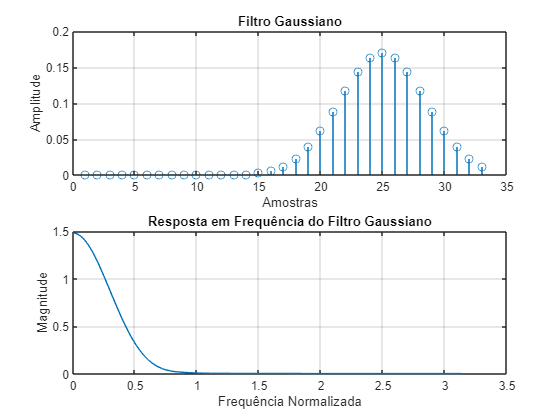

% Parâmetros
K0 = 0.17;
tau = 33e-9; % 33 ns 

% Vetor de amostras
span = 1; % número de símbolos para espalhar o pulso
ng = -span*k : span*k; % amostras de -span a +span símbolos

% Implementação do filtro gaussiano segundo a fórmula fornecida
g = K0 * exp( -pi * ( (ng*(T/k) - (T/2)) / tau ).^2 );

G = freqz(g,1,2048);
freq_g = linspace(0, pi, length(G));

figure;
subplot(2,1,1);
stem(g);
xlabel('Amostras');
ylabel('Amplitude');
title('Filtro Gaussiano');
grid on;

subplot(2,1,2);
plot(freq_g, abs(G)); 
xlabel('Frequência Normalizada');
ylabel('Magnitude');
title('Resposta em Frequência do Filtro Gaussiano');
grid on;

Como pode ser visto na figura acima, o filtro gaussiano apresenta uma transição suave no tempo, resultando em uma resposta em frequência mais suavizada. Quando comparado ao filtro retangular, que apresenta uma transição abrupta no tempo, de 1 a 0, a sua resposta em frequência apresenta lóbulas laterais em altas frequências. Ou seja, o filtro gaussiano tem um espectro limitado e largura de banda definida por $\frac{\sqrt{2}}{\tau }$ .

### 11. Considerando o bit stream na entrada do mapper dado por $B_1 =\left\lbrace \left\lbrack \ldotp \ldotp \ldotp 10011010\ldotp \ldotp \ldotp \right\rbrack \right\rbrace$ e o LPF gaussiano, repita os passos anteriores. Analise, interprete e comente os resultados. Compare os resultados com os obtidos com o filtro retangular nos domínios do tempo e da frequência. 

% Chamando a função QPSK_mapper
[I1, Q1] = mapper_QPSK(input_bits1);

% Exibindo os resultados
disp('Parte Real:');

Parte Real:


disp(I1);

     1    -1     1     1



disp('Parte Imaginária:');

Parte Imaginária:


disp(Q1);

    -1     1    -1    -1



% Plot constelação dos símbolos IQ
figure;
scatter(I1, Q1, 'filled');
xlabel('Parte Real (I)');
ylabel('Parte Imaginária (Q)');
title('Constelação QPSK');
grid on;
axis([-1.5 1.5 -1.5 1.5]);

% Upsampling de I e Q
I1_upsampled = upsample(I1, k);
Q1_upsampled = upsample(Q1, k);

% Vetor de tempo após o upsampling
t1_upsampled = (0:length(I1_upsampled)-1);

% Plot dos gráficos de I e Q após o upsampling
figure;
subplot(2, 1, 1);
stem(t1_upsampled, I1_upsampled, 'r', 'filled');
xlabel('Tempo');
ylabel('Valor');
title('Sinal de I após o upsampling');
grid on;

subplot(2, 1, 2);
stem(t1_upsampled, Q1_upsampled, 'b', 'filled');
xlabel('Tempo');
ylabel('Valor');
title('Sinal de Q após o upsampling');
grid on;

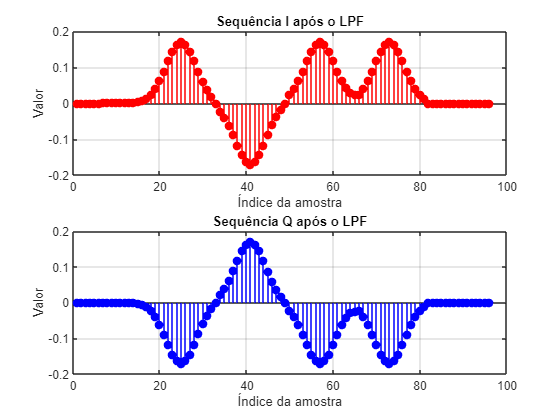

lpf_2 = g;

% Aplicação do LPF às sequências I e Q
I1_filtrado = conv(I1_upsampled,lpf_2);
Q1_filtrado = conv(Q1_upsampled,lpf_2);

% Plot dos gráficos de I e Q após o LPF 
figure; 
subplot(2,1,1);
stem(I1_filtrado, 'r', 'filled');
xlabel('Índice da amostra');
ylabel('Valor');
title('Sequência I após o LPF');
grid on;

subplot(2,1,2);
stem(Q1_filtrado, 'b', 'filled');
xlabel('Índice da amostra');
ylabel('Valor');
title('Sequência Q após o LPF');
grid on;

Como pode ser visto na figura acima, a sequencia IQ após upsample é convoluída com o filtro gaussiano e obtemos as sequências IQ após o LPF. Como o símbolo 01(I = -1 e Q = 1) e os demais símbolos 10(I = 1 e Q = -1), o comportamento esperado está correto. O próximo passo é realizar a heterodinação.

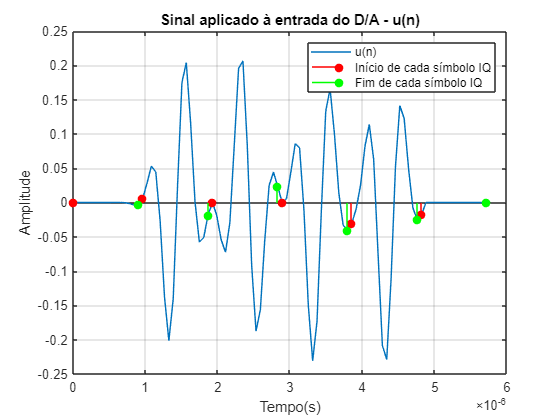

N1 = length(I1_filtrado);
n1 = 0:N1-1;

% Sinal da portadora
carrier_I1 = cos(2*pi*(Fc/Fs)*n1);
carrier_Q1 = sin(2*pi*(Fc/Fs)*n1);

% Heterodinação
u1 = I1_filtrado .* carrier_I1 - Q1_filtrado .* carrier_Q1;

t1 = 0:T:(length(I1_filtrado)-1)*T;

% Plot de u(n)
figure; 
plot(t1,u1);
xlabel('Tempo(s)');
ylabel('Amplitude');
title('Sinal aplicado à entrada do D/A - u(n)');
grid on;

% Identificação do início e fim de cada símbolo IQ
hold on;
stem(t1(1:k:end), u1(1:k:end), 'r', 'filled');
stem(t1(16:k:end), u1(16:k:end), 'g', 'filled');
legend('u(n)', 'Início de cada símbolo IQ', 'Fim de cada símbolo IQ');

O DDS usa uma portadora para realizar a heterodinação, que translada o sinal de banda base para banda passante. Como pode ser visto acima, o sinal aplicado à entrada do D/A é um sinal com inversão de fase, já que temos dois símbolos distantes em ${180}^{\circ }$. Essa inversão de fase pode ser vista em $2\mu s$ e $3\mu s$.

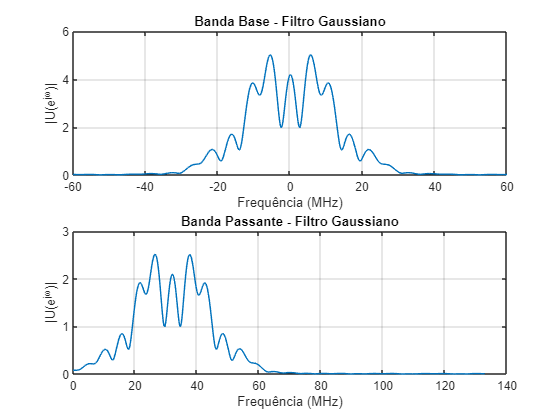

U1 = fft(u1,1024);
U1 = U1(1:(length(U1))/2);

% Frequências normalizadas 
omega1 = linspace(0, pi, length(U1));

% Convertendo para frequências em MHz
f_MHz_U1 = omega1/pi * (Fs/2)/1e6;

% Obtendo o espectro em banda base
bb_gau = I1_filtrado + 1j*Q1_filtrado;
BB_gau = fftshift(fft(bb_gau,1024));
fBB_gau = linspace(-Fs/2,Fs/2, length(BB_gau))/1e6;

% Plot do módulo de U(e^(jw))
figure; 
subplot(2,1,1);
plot(fBB_gau, abs(BB_gau));
xlabel('Frequência (MHz)');
xlim([-60 60]);
ylabel('|U(e^{j\omega})|');
title('Banda Base - Filtro Gaussiano');
grid on;

subplot(2,1,2);
plot(f_MHz_U1, abs(U1));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Banda Passante - Filtro Gaussiano');
grid on;

É notório que ao realizar a translação em frequência ($f=32$MHz) a largura de banda duplica e a amplitude é reduzida pela metade. Este comportamento é esperado já que ao transladar o sinal é realizada a operação $\frac{1}{2}\left\lbrack G\left(f-f_0 \right)+G\left(f+f_0 \right)\right\rbrack \ldotp$ Importante salientar que a análise é feita apenas na componente espectral positiva.

Comparando ao filtro retangular, o espectro do sinal utilizando o filtro gaussiano é muito mais limitado, ou seja, sem os lóbulos laterais. Além disso tem uma largura de banda definida analiticamente por $\mathrm{BW}=\frac{\sqrt{2}}{\tau }$.

BW_gau = sqrt(2)/tau;
fprintf('Banda Base analítica = %.2f MHz\n', (BW_gau)/1e6);

Banda Base analítica = 42.85 MHz


fprintf('Banda Passante analítica = %.2f MHz\n', 2*BW_gau/1e6);

Banda Passante analítica = 85.71 MHz


Como pode ser visto nos resultados obtidos acima, e comparando ao espectro em banda base e banda passante, os valores obtidos para a largura de banda são coerentes.

### 12. Substitua o LPF pelo filtro FIR root raised cosine (RRC).

### 13. Plote a resposta ao impulso e resposta em frequência do filtro root raised cosine. Compare com a resposta dos filtros anteriores.

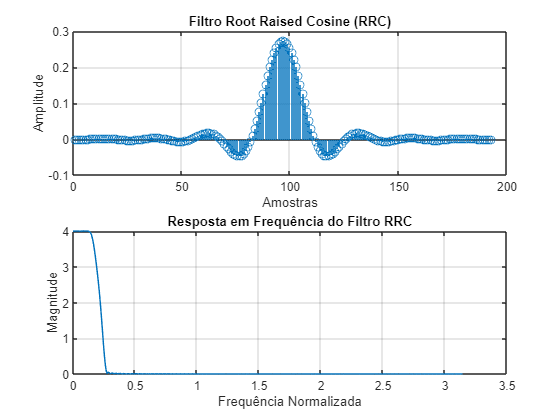

% Parâmetros do filtro 
alpha = 0.35;     % Fator de roll-off 
span_rrc = 12;    % Duração do filtro em símbolos

% Criando o filtro RRC
rrc = rcosdesign(alpha, span_rrc, k, 'sqrt');

RRC = freqz(rrc,1,2048);
freq_RRC = linspace(0, pi, length(RRC));

% Visualizar o filtro
figure;
subplot(2,1,1);
stem(rrc);
xlabel('Amostras');
ylabel('Amplitude');
title('Filtro Root Raised Cosine (RRC)');
grid on;

subplot(2,1,2);
plot(freq_RRC, abs(RRC)); 
xlabel('Frequência Normalizada');
ylabel('Magnitude');
title('Resposta em Frequência do Filtro RRC');
grid on;

A resposta ao impulso do filtro RRC tem uma duração de vários períodos de símbolo 𝑇 , o que é desejado para efeito de aumentar o intervalo em que a correlação é efetuada. A resposta ao impulso cruza por zero a cada 𝑡 = 𝑘𝑇 , com 𝑘 inteiro. A resposta em frequência do filtro é um passa baixa mais íngrime em comparação com o filtro gaussiano e com largura de banda definida $\mathrm{BW}=\mathrm{SR}\left(1+\alpha \right)$, e também espectro limitado diferentemente do retangular que apresenta lóbulos laterais.

### 14. Gere uma sequência aleatória de 10000 bits e calcule a largura de banda do sinal e verifique se o valor confere com o esperado.

[I2, Q2] = mapper_QPSK(bitstream);

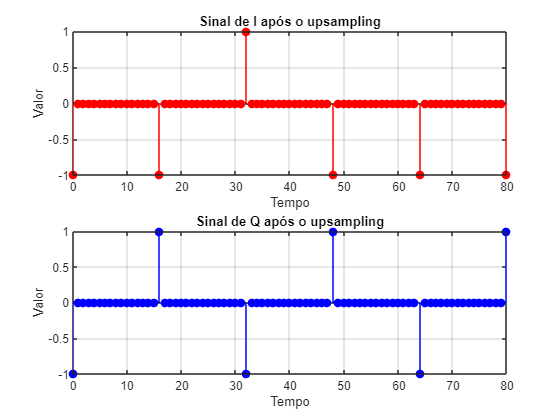

% Upsampling de I e Q
I2_upsampled = upsample(I2, k);
Q2_upsampled = upsample(Q2, k);

% Vetor de tempo após o upsampling
t2_upsampled = (0:length(I2_upsampled)-1);

% Plot dos gráficos de I e Q após o upsampling
figure;
subplot(2, 1, 1);
stem(t2_upsampled, I2_upsampled, 'r', 'filled');
xlabel('Tempo');
xlim([0 80]);
ylabel('Valor');
title('Sinal de I após o upsampling');
grid on;

subplot(2, 1, 2);
stem(t2_upsampled, Q2_upsampled, 'b', 'filled');
xlabel('Tempo');
xlim([0 80]);
ylabel('Valor');
title('Sinal de Q após o upsampling');
grid on;

Sequência de I e Q após upsample, o eixo X foi limitado para permitir uma melhor visualização.

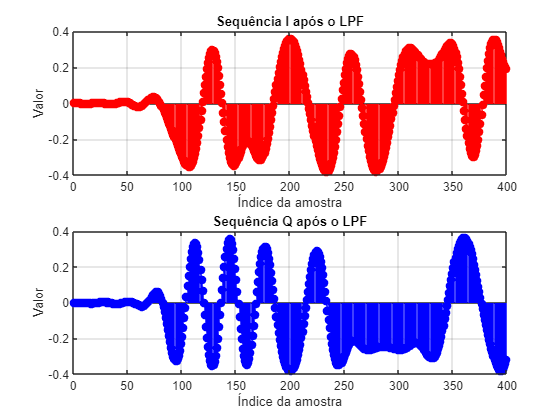

lpf_3 = rrc;

% Aplicação do LPF às sequências I e Q
I2_filtrado = conv(I2_upsampled,lpf_3);
Q2_filtrado = conv(Q2_upsampled,lpf_3);

% Plot dos gráficos de I e Q após o LPF 
figure; 
subplot(2,1,1);
stem(I2_filtrado, 'r', 'filled');
xlabel('Índice da amostra');
xlim([0 400]);
ylabel('Valor');
title('Sequência I após o LPF');
grid on;

subplot(2,1,2);
stem(Q2_filtrado, 'b', 'filled');
xlabel('Índice da amostra');
xlim([0 400]);
ylabel('Valor');
title('Sequência Q após o LPF');
grid on;

Como pode ser visto na figura acima, a sequencia IQ após upsample é convoluída com o filtro RRC e obtemos as sequências IQ após o LPF. O próximo passo é realizar a heterodinação.

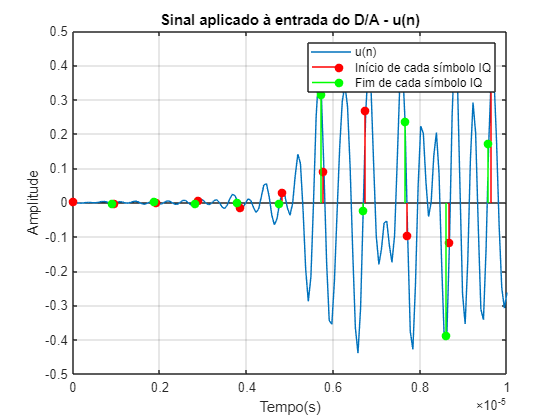

N2 = length(I2_filtrado);
n2 = 0:N2-1;

% Sinal da portadora
carrier_I2 = cos(2*pi*(Fc/Fs)*n2);
carrier_Q2 = sin(2*pi*(Fc/Fs)*n2);

% Heterodinação
u2 = I2_filtrado .* carrier_I2 - Q2_filtrado .* carrier_Q2;

t2 = 0:T:(length(I2_filtrado)-1)*T;

% Plot de u(n)
figure; 
plot(t2,u2);
xlabel('Tempo(s)');
xlim([0 0.1e-4]);
ylabel('Amplitude');
title('Sinal aplicado à entrada do D/A - u(n)');
grid on;

% Identificação do início e fim de cada símbolo IQ
hold on;
stem(t2(1:k:end), u2(1:k:end), 'r', 'filled');
stem(t2(16:k:end), u2(16:k:end), 'g', 'filled');
legend('u(n)', 'Início de cada símbolo IQ', 'Fim de cada símbolo IQ');

O DDS usa uma portadora para realizar a heterodinação, que translada o sinal de banda base para banda passante. Como pode ser visto acima, o sinal aplicado à entrada do D/A é um sinal com inversão de fase, já que temos bits aleatórios e ocorrem símbolos distantes em ${180}^{\circ }$. O sinal plotado está limitado no eixo X para uma visualização melhor.

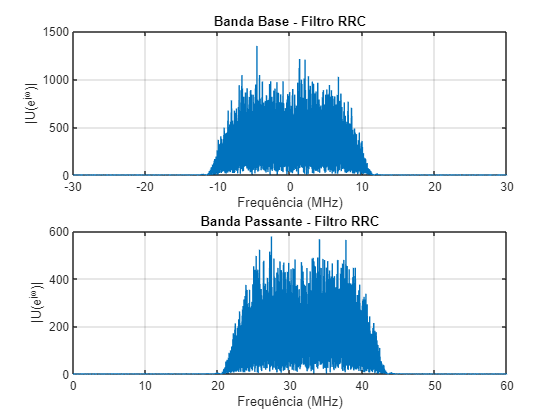

U2 = fft(u2);
U2 = U2(1:(length(U2))/2);

% Frequências normalizadas 
omega2 = linspace(0, pi, length(U2));

% Convertendo para frequências em MHz
f_MHz_U2 = omega2/pi * (Fs/2)/1e6;

% Obtendo o espectro em banda base
bb_rrc = I2_filtrado + 1j*Q2_filtrado;
BB_rrc = fftshift(fft(bb_rrc));
fBB_rrc = linspace(-Fs/2,Fs/2, length(bb_rrc))/1e6;

% Plot do módulo de U(e^(jw))
figure;
subplot(2,1,1);
plot(fBB_rrc, abs(BB_rrc));
xlabel('Frequência (MHz)');
xlim([-30 30]);
ylabel('|U(e^{j\omega})|');
title('Banda Base - Filtro RRC');
grid on;

subplot(2,1,2);
plot(f_MHz_U2, abs(U2));
xlabel('Frequência (MHz)');
xlim([0 60]);
ylabel('|U(e^{j\omega})|');
title('Banda Passante - Filtro RRC');
grid on;

É notório que ao realizar a translação em frequência ($f=32$MHz) a largura de banda duplica e a amplitude é reduzida pela metade. Este comportamento é esperado já que ao transladar o sinal é realizada a operação $\frac{1}{2}\left\lbrack G\left(f-f_0 \right)+G\left(f+f_0 \right)\right\rbrack \ldotp$ Importante salientar que a análise é feita apenas na componente espectral positiva.

Comparando ao filtro retangular, o espectro do sinal utilizando o filtro RRC é muito mais limitado, ou seja, sem os lóbulos laterais. Além disso tem uma largura de banda definida analiticamente por $\mathrm{BW}=\mathrm{SR}\left(1+\alpha \right)$. Em comparação ao filtro gaussiano, o filtro RRC apresenta uma largura de banda menor porque a resposta em frequência do filtro é mais íngrime. Além disso, é possível notar os espúrios gerados pelos símbolos distantes em ${180}^{\circ }$.

BW_RRC = SR*(1 + alpha);
fprintf('Banda Passante analítica = %.2f MHz\n', BW_RRC/1e6);

Banda Passante analítica = 22.41 MHz


fprintf('Banda Base analítica = %.2f MHz\n', (BW_RRC/2)/1e6);

Banda Base analítica = 11.21 MHz


Como pode ser visto nos resultados obtidos acima, e comparando ao espectro em banda base e banda passante, os valores obtidos para a largura de banda são coerentes.

### 15. Reduza o fator de upsample 𝑘 pela metade e dobre o symbol rate 𝑆𝑅, de modo a manter a mesma frequência de amostragem 𝐹𝑠 . Implemente o modulador para esta nova situação operacional, utilizando um filtro RRC adequado. Compare os resultados com os obtidos anteriormente, utilizando filtro RRC.

kn = k/2;
SRn = 2*SR;
Tn = 1/SRn;

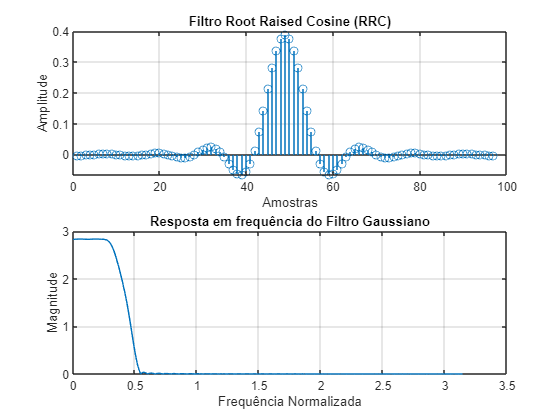

% Criando o filtro RRC
rrcn = rcosdesign(alpha, span_rrc, kn, 'sqrt');

%RRCn = fftshift(fft(rrcn));
%freq_RRCn = linspace(-pi, pi, length(RRCn));

RRCn = freqz(rrcn,1,2048);
freq_RRCn = linspace(0, pi, length(RRCn));

% Visualizar o filtro
figure;
subplot(2,1,1);
stem(rrcn);
xlabel('Amostras');
ylabel('Amplitude');
title('Filtro Root Raised Cosine (RRC)');
grid on;

subplot(2,1,2);
plot(freq_RRCn, abs(RRCn)); 
xlabel('Frequência Normalizada');
ylabel('Magnitude');
title('Resposta em frequência do Filtro Gaussiano');
grid on;

Como o fator de upsample e Symbol Rate foram alterados, a resposta ao impulso e em frequência do filtro não é mais a mesma. Em consequência a largura de banda do filtro é maior, já que $\mathrm{BW}=\mathrm{SR}\left(1+\alpha \right)\ldotp$

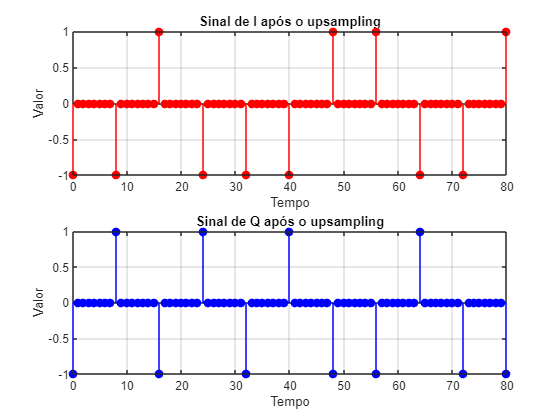

% Upsampling de I e Q
I2n_upsampled = upsample(I2, kn);
Q2n_upsampled = upsample(Q2, kn);

% Vetor de tempo após o upsampling
t2n_upsampled = (0:length(I2n_upsampled)-1);

% Plot dos gráficos de I e Q após o upsampling
figure;
subplot(2, 1, 1);
stem(t2n_upsampled, I2n_upsampled, 'r', 'filled');
xlabel('Tempo');
xlim([0 80]);
ylabel('Valor');
title('Sinal de I após o upsampling');
grid on;

subplot(2, 1, 2);
stem(t2n_upsampled, Q2n_upsampled, 'b', 'filled');
xlabel('Tempo');
xlim([0 80]);
ylabel('Valor');
title('Sinal de Q após o upsampling');
grid on;

O fator de upsample foi alterado, logo temos o símbolo I e Q e 7 amostras nulas (k-1) com k=8 para este cenário. O eixo X foi limitado para uma melhor visualização.

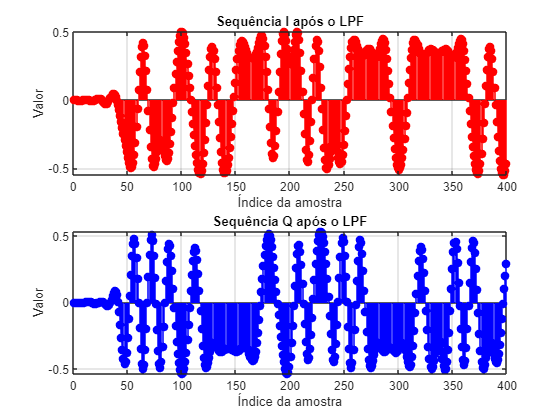

lpf_4 = rrcn;

% Aplicação do LPF às sequências I e Q
I2n_filtrado = conv(I2n_upsampled,lpf_4);
Q2n_filtrado = conv(Q2n_upsampled,lpf_4);

% Plot dos gráficos de I e Q após o LPF 
figure; 
subplot(2,1,1);
stem(I2n_filtrado, 'r', 'filled');
xlabel('Índice da amostra');
xlim([0 400]);
ylabel('Valor');
title('Sequência I após o LPF');
grid on;

subplot(2,1,2);
stem(Q2n_filtrado, 'b', 'filled');
xlabel('Índice da amostra');
xlim([0 400]);
ylabel('Valor');
title('Sequência Q após o LPF');
grid on;

Como pode ser visto na figura acima, a sequencia IQ após upsample é convoluída com o filtro RRC e obtemos as sequências IQ após o LPF. O próximo passo é realizar a heterodinação.

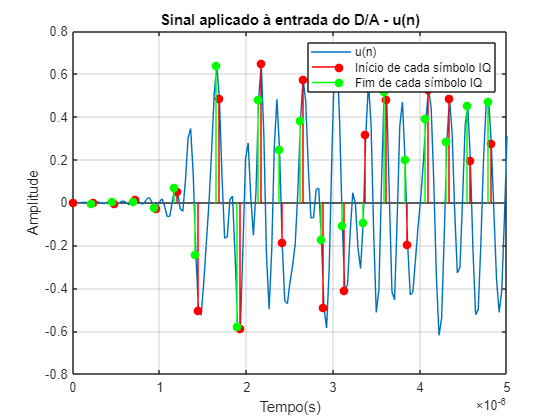

N3 = length(I2n_filtrado);
n3 = 0:N3-1;

% Sinal da portadora
carrier_I2n = cos(2*pi*(Fc/Fs)*n3);
carrier_Q2n = sin(2*pi*(Fc/Fs)*n3);

% Heterodinação
u3 = I2n_filtrado .* carrier_I2n - Q2n_filtrado .* carrier_Q2n;

t3 = 0:Tn:(length(I2n_filtrado)-1)*Tn;

% Plot de u(n)
figure; 
plot(t3,u3);
xlabel('Tempo(s)');
xlim([0 0.05e-4]);
ylabel('Amplitude');
title('Sinal aplicado à entrada do D/A - u(n)');
grid on;

% Identificação do início e fim de cada símbolo IQ
hold on;
stem(t3(1:kn:end), u3(1:kn:end), 'r', 'filled');
stem(t3(kn:kn:end), u3(kn:kn:end), 'g', 'filled');
legend('u(n)', 'Início de cada símbolo IQ', 'Fim de cada símbolo IQ');

O DDS usa uma portadora para realizar a heterodinação, que translada o sinal de banda base para banda passante. Como pode ser visto acima, o sinal aplicado à entrada do D/A é um sinal com inversão de fase, já que temos bits aleatórios e ocorrem símbolos distantes em ${180}^{\circ }$. O sinal plotado está limitado no eixo X para uma visualização melhor.

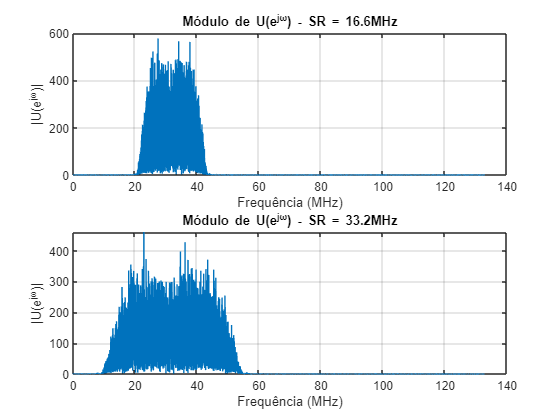

U3 = fft(u3);
U3 = U3(1:(length(U3))/2);

% Frequências normalizadas 
omega3 = linspace(0, pi, length(U3));

% Convertendo para frequências em MHz
f_MHz_U3 = omega3/pi * (Fs/2)/1e6;

% Plot do módulo de U(e^(jw))
figure; 
subplot(2,1,1);
plot(f_MHz_U2, abs(U2));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Módulo de U(e^{j\omega}) - SR = 16.6MHz');
grid on;

subplot(2,1,2);
plot(f_MHz_U3, abs(U3));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Módulo de U(e^{j\omega}) - SR = 33.2MHz');
grid on;

É notório que ao realizar a translação em frequência ($f=32$MHz) a largura de banda duplica e a amplitude é reduzida pela metade. Este comportamento é esperado já que ao transladar o sinal é realizada a operação $\frac{1}{2}\left\lbrack G\left(f-f_0 \right)+G\left(f+f_0 \right)\right\rbrack \ldotp$ Importante salientar que a análise é feita apenas na componente espectral positiva.

Como o filtro RRC tem uma largura de banda definida analiticamente por $\mathrm{BW}=\mathrm{SR}\left(1+\alpha \right)$, ao duplicar o Symbol Rate do sistema, a largura de banda é também duplicada. Além disso, é possível notar os espúrios gerados pelos símbolos distantes em ${180}^{\circ }$.

BW_RRCn = SRn*(1 + alpha);

fprintf('BW analítica (SR = 16.6MHz) = %.2f MHz\n', BW_RRC/1e6);

BW analítica (SR = 16.6MHz) = 22.41 MHz


fprintf('BW analítica (SR = 33.2 MHz) = %.2f MHz\n', BW_RRCn/1e6);

BW analítica (SR = 33.2 MHz) = 44.82 MHz


Como pode ser visto nos resultados obtidos acima, e comparando ao espectro em banda passante com as modificações de $k$ e $\mathrm{SR}$, os valores obtidos para a largura de banda são coerentes.

### 16. Considerando a sequência aleatória de 10000 bits, repita os passos anteriores, comparando os resultados dos três LPFs implementados: retangular, gaussiano e root raised cosine. Faça uma análise a respeito dos seguintes tópicos: 

- Como as transições suaves/abruptas no domínio do tempo impactam no espectro do sinal (domínio da frequência). 

- Largura de banda do sinal em banda-base versus largura de banda do sinal em bandapassante. 

- Resposta em frequência do LPF / contenção espectral.

### **A ANÁLISE DESTE ITEM ESTÁ NO ÚLTIMO PLOT, ESTE PLOT CONTÉM TODOS OS FILTROS EM BANDA BASE E BANDA PASSANTE.**

### Foi utilizado os dados originais, SR = 16.6MHz e k = 16.

#### Filtro Retangular

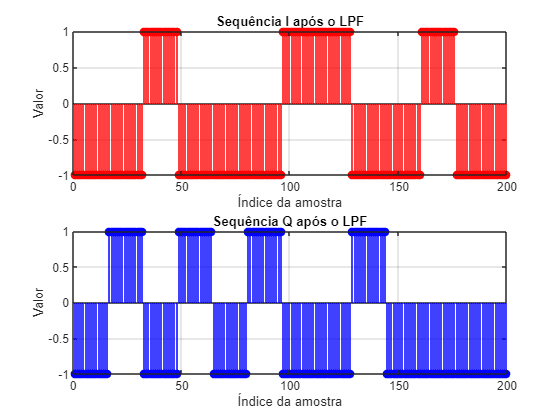

I3_filtrado = conv(I2_upsampled,lpf_1);
Q3_filtrado = conv(Q2_upsampled,lpf_1);

% Plot dos gráficos de I e Q após o LPF 
figure; 
subplot(2,1,1);
stem(I3_filtrado, 'r', 'filled');
xlabel('Índice da amostra');
xlim([0 200]);
ylabel('Valor');
title('Sequência I após o LPF');
grid on;

subplot(2,1,2);
stem(Q3_filtrado, 'b', 'filled');
xlabel('Índice da amostra');
xlim([0 200]);
ylabel('Valor');
title('Sequência Q após o LPF');
grid on;

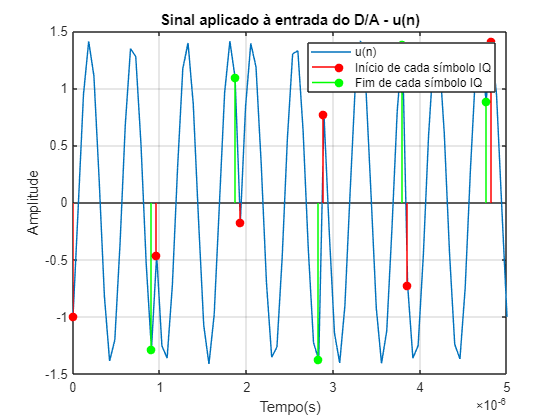

N4 = length(I3_filtrado);
n4 = 0:N4-1;

% Sinal da portadora
carrier_I3 = cos(2*pi*(Fc/Fs)*n4);
carrier_Q3 = sin(2*pi*(Fc/Fs)*n4);

% Heterodinação
u4 = I3_filtrado .* carrier_I3 - Q3_filtrado .* carrier_Q3;

t4 = 0:T:(length(I3_filtrado)-1)*T;

% Plot de u(n)
figure; 
plot(t4,u4);
xlabel('Tempo(s)');
xlim([0 0.05e-4]);
ylabel('Amplitude');
title('Sinal aplicado à entrada do D/A - u(n)');
grid on;

% Identificação do início e fim de cada símbolo IQ
hold on;
stem(t4(1:k:end), u4(1:k:end), 'r', 'filled');
stem(t4(16:k:end), u4(16:k:end), 'g', 'filled');
legend('u(n)', 'Início de cada símbolo IQ', 'Fim de cada símbolo IQ');

U4 = fft(u4);
U4 = U4(1:(length(U4))/2);

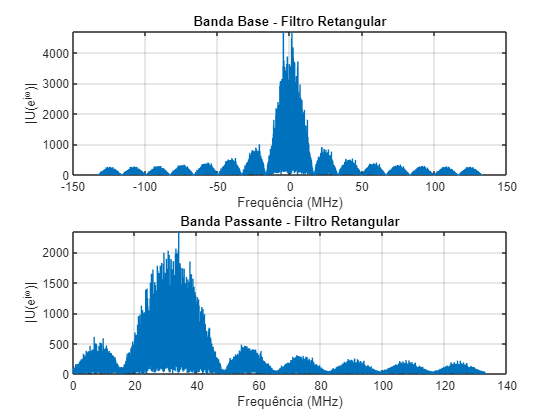


% Frequências normalizadas 
omega4 = linspace(0, pi, length(U4));

% Convertendo para frequências em MHz
f_MHz_U4 = omega4/pi * (Fs/2)/1e6;

% Obtendo o espectro em banda base
bb_ret1 = I3_filtrado + 1j*Q3_filtrado;
BB_ret1 = fftshift(fft(bb_ret1));
fBB_ret1 = linspace(-Fs/2,Fs/2, length(bb_ret1))/1e6;

% Plot do módulo de U(e^(jw))
figure;
subplot(2,1,1);
plot(fBB_ret1, abs(BB_ret1));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Banda Base - Filtro Retangular');
grid on;

subplot(2,1,2)
plot(f_MHz_U4, abs(U4));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Banda Passante - Filtro Retangular');
grid on;

#### Filtro Gaussiano

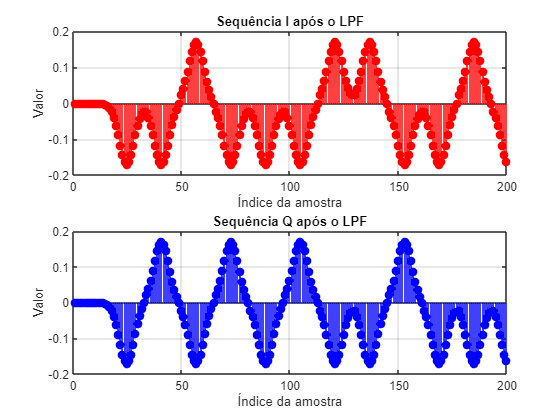

I4_filtrado = conv(I2_upsampled,lpf_2);
Q4_filtrado = conv(Q2_upsampled,lpf_2);

% Plot dos gráficos de I e Q após o LPF 
figure; 
subplot(2,1,1);
stem(I4_filtrado, 'r', 'filled');
xlabel('Índice da amostra');
xlim([0 200]);
ylabel('Valor');
title('Sequência I após o LPF');
grid on;

subplot(2,1,2);
stem(Q4_filtrado, 'b', 'filled');
xlabel('Índice da amostra');
xlim([0 200]);
ylabel('Valor');
title('Sequência Q após o LPF');
grid on;

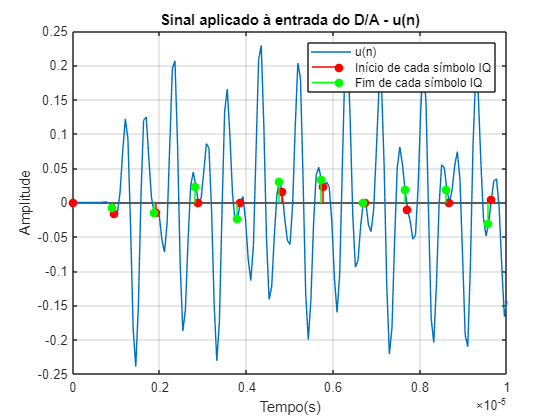

N5 = length(I4_filtrado);
n5 = 0:N5-1;

% Sinal da portadora
carrier_I4 = cos(2*pi*(Fc/Fs)*n5);
carrier_Q4 = sin(2*pi*(Fc/Fs)*n5);

% Heterodinação
u5 = I4_filtrado .* carrier_I4 - Q4_filtrado .* carrier_Q4;

t5 = 0:T:(length(I4_filtrado)-1)*T;

% Plot de u(n)
figure; 
plot(t5,u5);
xlabel('Tempo(s)');
xlim([0 0.1e-4]);
ylabel('Amplitude');
title('Sinal aplicado à entrada do D/A - u(n)');
grid on;

% Identificação do início e fim de cada símbolo IQ
hold on;
stem(t5(1:k:end), u5(1:k:end), 'r', 'filled');
stem(t5(16:k:end), u5(16:k:end), 'g', 'filled');
legend('u(n)', 'Início de cada símbolo IQ', 'Fim de cada símbolo IQ');

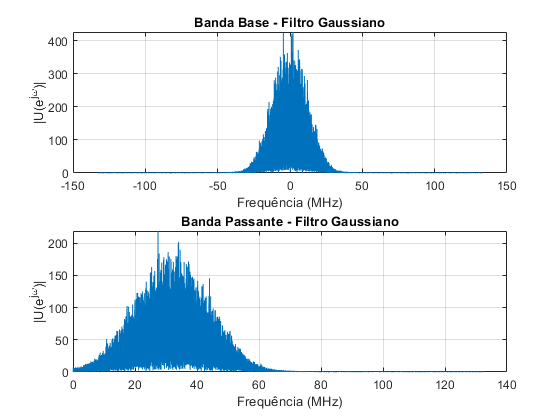

U5 = fft(u5);
U5 = U5(1:(length(U5))/2);

% Frequências normalizadas 
omega5 = linspace(0, pi, length(U5));

% Convertendo para frequências em MHz
f_MHz_U5 = omega5/pi * (Fs/2)/1e6;

% Obtendo o espectro em banda base
bb_gau1 = I4_filtrado + 1j*Q4_filtrado;
BB_gau1 = fftshift(fft(bb_gau1));
fBB_gau1 = linspace(-Fs/2,Fs/2, length(bb_gau1))/1e6;

% Plot do módulo de U(e^(jw))
figure;
subplot(2,1,1);
plot(fBB_gau1, abs(BB_gau1));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Banda Base - Filtro Gaussiano');
grid on;

subplot(2,1,2)
plot(f_MHz_U5, abs(U5));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Banda Passante - Filtro Gaussiano');
grid on;

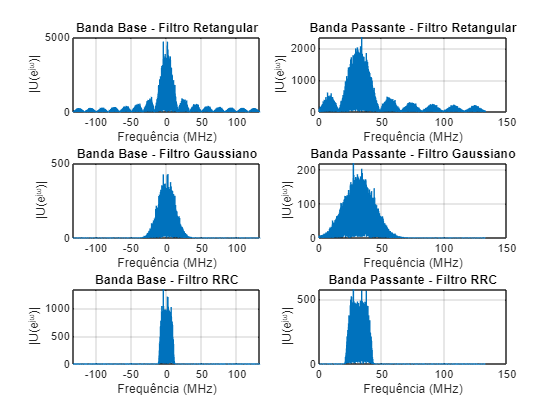

figure;
subplot(3,2,2);
plot(f_MHz_U4, abs(U4));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Banda Passante - Filtro Retangular');
grid on;

subplot(3,2,1);
plot(fBB_ret1, abs(BB_ret1));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Banda Base - Filtro Retangular');
grid on;

subplot(3,2,4);
plot(f_MHz_U5, abs(U5));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Banda Passante - Filtro Gaussiano');
grid on;

subplot(3,2,3);
plot(fBB_gau1, abs(BB_gau1));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Banda Base - Filtro Gaussiano');
grid on;

subplot(3,2,6);
plot(f_MHz_U2, abs(U2));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Banda Passante - Filtro RRC');
grid on;

subplot(3,2,5);
plot(fBB_rrc, abs(BB_rrc));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
title('Banda Base - Filtro RRC');
grid on;

A partir da figura acima, fica mais fácil de comparar os três filtros implementados.

O filtro retangular apresenta transição abrupta no tempo, em que sua resposta em frequência seja uma sinc(x) e apresente lóbulos laterais decrescentes, abrangendo altas frequências.

O filtro gaussiano apresenta em sua resposta ao impulso uma transição suave, em que sua resposta em frequência seja um filtro passa baixas com espectro limitado e largura de banda $\mathrm{BW}=\frac{\sqrt{2}}{\tau }$.

A resposta ao impulso do filtro RRC tem uma duração de vários períodos de símbolo 𝑇 , o que é desejado para efeito de aumentar o intervalo em que a correlação é efetuada. A resposta ao impulso cruza por zero a cada 𝑡 = 𝑘𝑇 , com 𝑘 inteiro. A resposta em frequência do filtro é um passa baixa mais íngrime em comparação com o filtro gaussiano e com largura de banda definida $\textrm{BW}=\textrm{SR}\left(1+\alpha \right)$, e também espectro limitado diferentemente do retangular que apresenta lóbulos laterais.

Além da análise entre os filtros, é importante considerar que ao realizar a heterodinação, translação em frequência, a largura de banda duplica e por consequência a amplitude cai pela metade pela operação  $\frac{1}{2}\left\lbrack G\left(f-f_0 \right)+G\left(f+f_0 \right)\right\rbrack \ldotp$ Importante salientar que a análise é feita apenas na componente espectral positiva.

## PARTE 2

### 1. Implemente um modulador 16-QAM que opere nas mesmas condições do modulador implementado na Parte I. Para tal, é necessário apenas substituir o mapper QPSK por um mapper 16-QAM, de acordo com a constelação apresentada na Figura 4. Implemente o mapper 16-QAM através de uma função. 

### 2. Verifique o funcionamento do modulador 16-QAM, aplicando em sua entrada uma sequência de bits que gere todos os símbolos da constelação. Certifique-se de que o mapeamento está implementado corretamente.

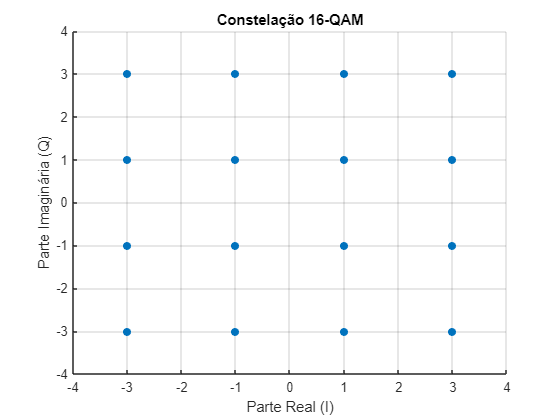

[I16, Q16] = qam16_mapper(bitstream);

figure;
scatter(I16, Q16, 'filled');
xlabel('Parte Real (I)');
ylabel('Parte Imaginária (Q)');
title('Constelação 16-QAM');
grid on;
axis([-4 4 -4 4]);

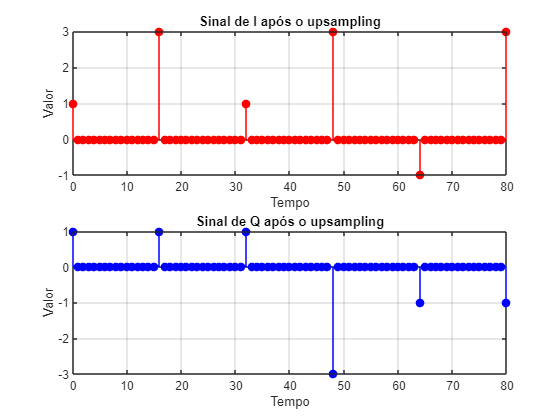

% Upsampling de I e Q
I16_upsampled = upsample(I16, k);
Q16_upsampled = upsample(Q16, k);

% Vetor de tempo após o upsampling
t16_upsampled = (0:length(I16_upsampled)-1);

% Plot dos gráficos de I e Q após o upsampling
figure;
subplot(2, 1, 1);
stem(t16_upsampled, I16_upsampled, 'r', 'filled');
xlabel('Tempo');
xlim([0 80]);
ylabel('Valor');
title('Sinal de I após o upsampling');
grid on;

subplot(2, 1, 2);
stem(t16_upsampled, Q16_upsampled, 'b', 'filled');
xlabel('Tempo');
xlim([0 80]);
ylabel('Valor');
title('Sinal de Q após o upsampling');
grid on;

Diferentemente da modulação QPSK, a modulação 16-QAM, apresenta 3 amplitudes, que por consequência I e Q pode apresentar 4 possíveis valores (-1,-3, 1, 3). Neste plot que está limitado para uma melhor visualização, podemos ver que I e Q estão tendo valores variados entre (-1,-3, 1, 3), em que os valores de símbolo são obtidos através do bitstream aleatório de entrada.

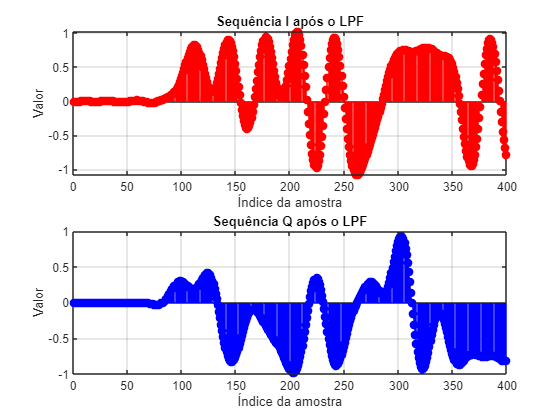

% Aplicação do LPF às sequências I e Q
I16_filtrado = conv(I16_upsampled,lpf_3);
Q16_filtrado = conv(Q16_upsampled,lpf_3);

% Plot dos gráficos de I e Q após o LPF 
figure; 
subplot(2,1,1);
stem(I16_filtrado, 'r', 'filled');
xlabel('Índice da amostra');
xlim([0 400]);
ylabel('Valor');
title('Sequência I após o LPF');
grid on;

subplot(2,1,2);
stem(Q16_filtrado, 'b', 'filled');
xlabel('Índice da amostra');
xlim([0 400]);
ylabel('Valor');
title('Sequência Q após o LPF');
grid on;

Como pode ser visto na figura acima, a sequência IQ após upsample é convoluída com o filtro RRC e obtemos as sequências IQ após o LPF. É possível notar a diferença de amplitude do pico do filtro RRC pela utilização da modulação 16-QAM. O próximo passo é realizar a heterodinação.

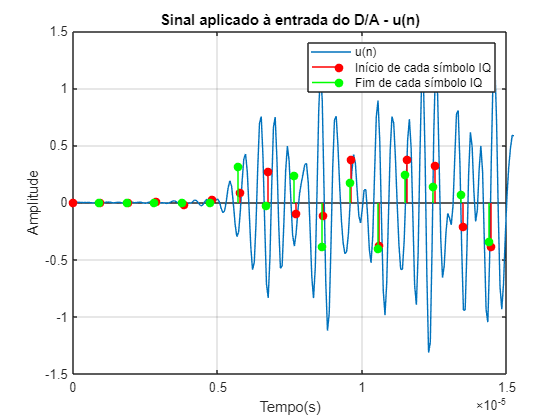

N16 = length(I16_filtrado);
n16 = 0:N16-1;

% Sinal da portadora
carrier_I16 = cos(2*pi*(Fc/Fs)*n16);
carrier_Q16 = sin(2*pi*(Fc/Fs)*n16);

% Heterodinação
u16 = I16_filtrado .* carrier_I16 - Q16_filtrado .* carrier_Q16;

t16 = 0:T:(length(I16_filtrado)-1)*T;

% Plot de u(n)
figure; 
plot(t16,u16);
xlabel('Tempo(s)');
xlim([0 0.15e-4]);
ylabel('Amplitude');
title('Sinal aplicado à entrada do D/A - u(n)');
grid on;

% Identificação do início e fim de cada símbolo IQ
hold on;
stem(t2(1:k:end), u2(1:k:end), 'r', 'filled');
stem(t2(16:k:end), u2(16:k:end), 'g', 'filled');
legend('u(n)', 'Início de cada símbolo IQ', 'Fim de cada símbolo IQ');

O DDS usa uma portadora para realizar a heterodinação, que translada o sinal de banda base para banda passante. Como pode ser visto acima, o sinal aplicado à entrada do D/A é um sinal com inversão de fase, já que temos bits aleatórios e ocorrem símbolos distantes em ${180}^{\circ } \;,{\mathrm{90}}^{\circ }$. O sinal plotado está limitado no eixo X para uma visualização melhor.

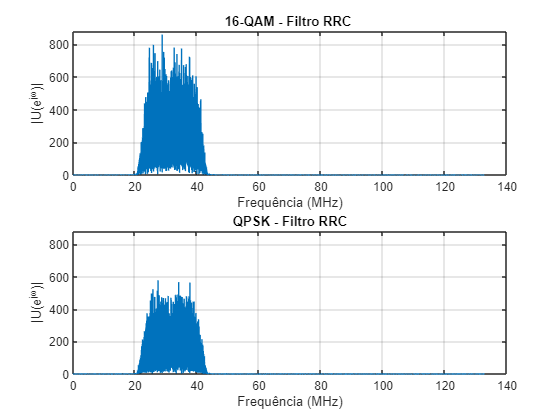

U16 = fft(u16);
U16 = U16(1:(length(U16))/2);

% Frequências normalizadas 
omega16 = linspace(0, pi, length(U16));

% Convertendo para frequências em MHz
f_MHz_U16 = omega16/pi * (Fs/2)/1e6;

% Plot do módulo de U(e^(jw))
figure; 
subplot(2,1,1);
plot(f_MHz_U16, abs(U16)); 
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
ylim([0 880]);
title('16-QAM - Filtro RRC ');
grid on;

subplot(2,1,2);
plot(f_MHz_U2, abs(U2));
xlabel('Frequência (MHz)');
ylabel('|U(e^{j\omega})|');
ylim([0 880]);
title('QPSK - Filtro RRC');
grid on;

Como podemos ver na imagem acima, as diferentes modulações apresentaram um espectro com a mesma largura de banda já que estamos usando o mesmo filtro RRC com o mesmo symbol rate. Contudo, a constelação 16-QAM tem maior energia média por símbolo e por bit do que QPSK, sendo que não estão normalizadas. Isso fica evidente pela amplitude do sinal no espectro plotado para as diferentes modulações. Embora, a modulação QPSK é mais robusta ao ruído pois há mais espaço entre os símbolos, enquanto a 16-QAM é mais suscetível ao erro.